# **Discrete Optimal Path Demo:**

## 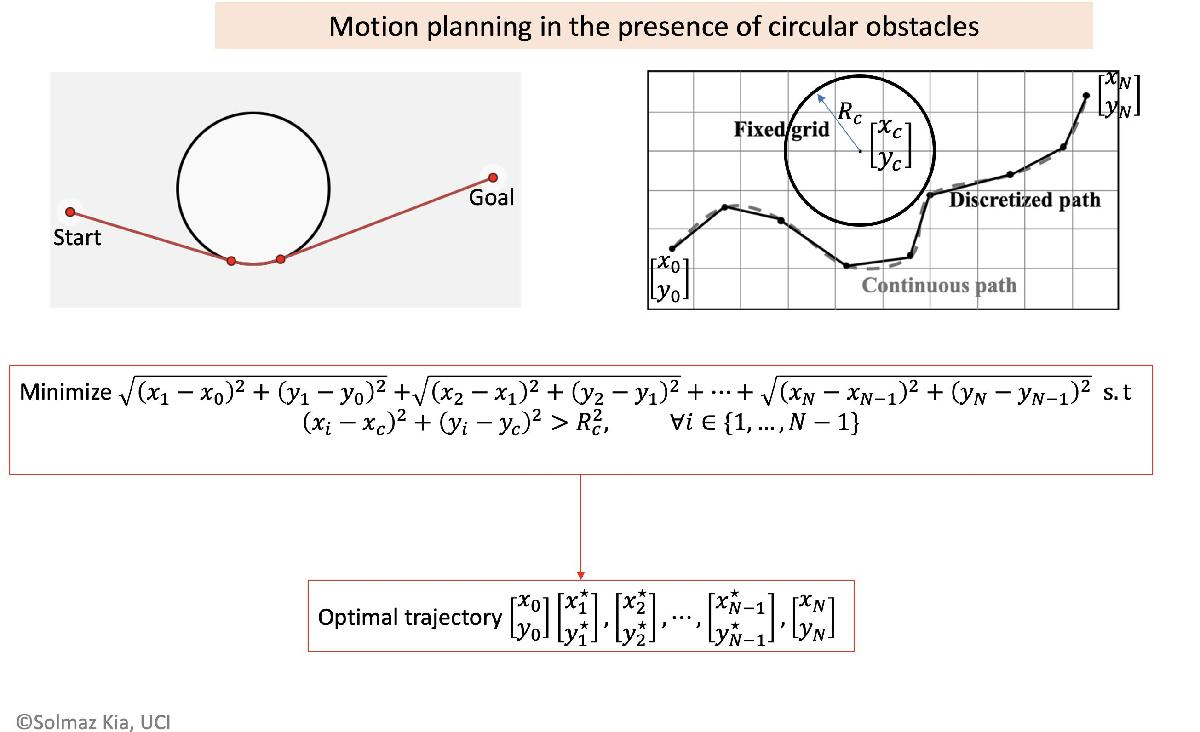

## Problem Formulation:

This script shows how we can find the shortest path from a start goal to an end goal through a field of obstacles.  We will solve for the optimal path using the following minimization:


$$  \begin{array}{ccc}
    \underset{\mathbf{x},\mathbf{y}}\text{min} & \sum_{i=1}^N\sqrt{(x_i-x_{i-1})^2 + (y_i-y_{i-1})^2} &  \\
    s.t. & (x_j - x_c)^2 + (y_j - y_c)^2 > R_c^2, &\forall j \in \{1,\ldots, N-1\} \\
    & (x_0,y_0) = (x_{start},y_{start}) \\
 & (x_N,y_N) = (x_{end},y_{end})
  \end{array}$$


This problem formulation minimizes the distance between a point and its neighbors along a discrete trajectory.  The first constraint enforces that the solution cannot intersect the obstacles.  It does this by checking if the point, (x_j,y_j), is not within the radius of the obstacle, R_c.  The second and third contstraint specify that the start and end points are fixed based on our desired start and end coordinates.  This demo shows how this solution can be implemented.

% preliminaries
clearvars
clf()
% global vars needed to get data from fmincon
addpath(fullfile('.', 'outputFcn_global'));
global outputFcn_global_data x_vals obstacles 

## One Obstacle Implementation:

The first step is to setup out course load an obstacle course.  There are some already provided in ./obstacle_envs.  We will also choose our start and end points.

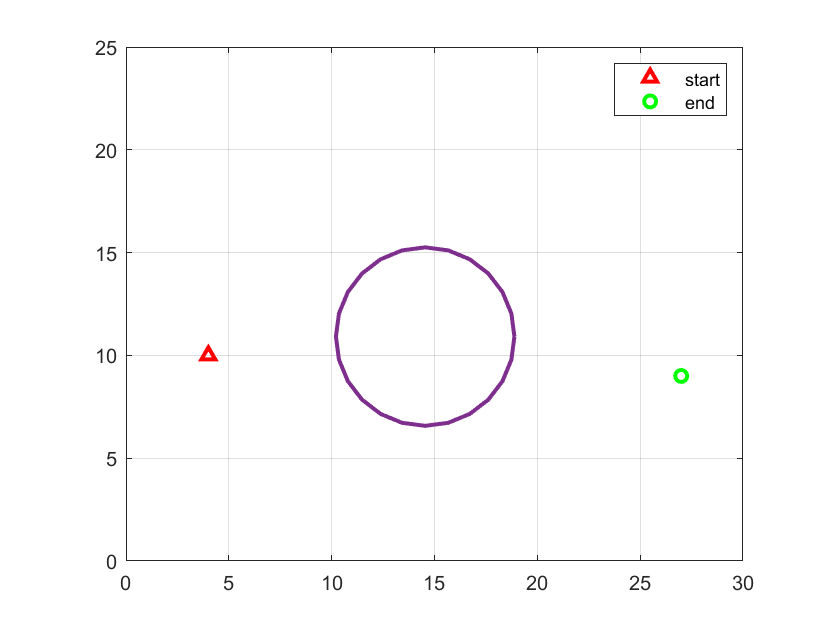

obstacle_file = "obstacle_envs/1_obstacle.txt";
use_ginput = false; % Recommend to enable this for second pass through document.  This enables the user to create an initial guess for the problem.
obstacles = read_obstacle_file(obstacle_file); % if obstacle file is changed, guess needs to be changed as well
figure(1)
if strcmp(obstacle_file,'obstacle_envs/1_obstacle.txt')
    x0 = 4; y0 = 10; xf = 27; yf = 9;
else
    x0 = 3; y0 = 6; xf = 26; yf = 18;
end
x_start = [x0,y0]; x_end = [xf,yf];
plot_env(x_start,x_end,obstacles)
make_legend('start','end','')

To find the optimal path from the start to end goal, we can take a guess at the optimal solution, and then use constrained optimization to find our best solution.  For now we will load an initial guess.  We will use a guess that goes around the bottom of this obstacle.  New initial guesses can be created with short_dist_multi_obs.m and saved to demo_guess.mat.

These guesses were made with dx = 0.5 between points on the discrete trajectory.

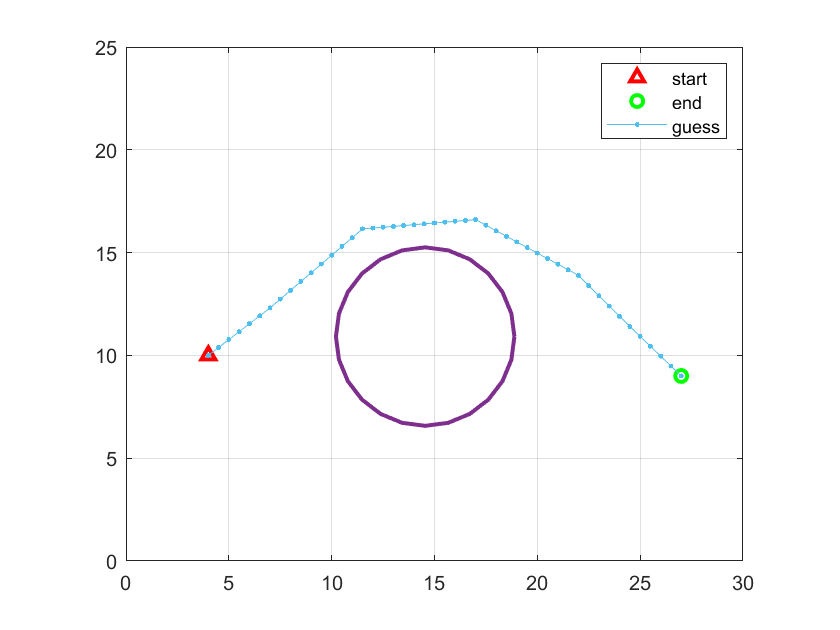

if ~use_ginput
    load('demo_guess.mat')
    x_span = x_one_obs;
    y_span_guess = y_one_obs_1; % guess below or above can be selected
else
    input_fig = figure(5);
    plot_env(x_start,x_end,obstacles)
    title(sprintf('Add Waypoints with left click\nFinish with right click'))
    dx = 0.5; % spacing between x points
    [x_span,y_span_guess,N] = make_input_guess(x_start,x_end,dx,0);
    close(input_fig) 
end
figure(2)
plot_env(x_start,x_end,obstacles)
plot_guess(x_span,y_span_guess)
make_legend('start','end','','guess')

With our guess and environment established, we are now ready to set up our minimization problem.  First we build our objective function, f, as the euclidean distance between each pair of points.  Our distance between x coordinates is a constant, dx, specified when making the guesses.


$$\sum_{i=1}^N\sqrt{(x_i-x_{i-1})^2 + (y_i-y_{i-1})^2}
$$


% build objective function
f = @(y)  sqrt(dx^2 + (y(1)-y0)^2);
for ii = 1:N-2
    f = @(y) f(y) + sqrt(dx^2 + (y(ii+1)-y(ii))^2);
end
f = @(y) f(y) + sqrt(dx^2 + (yf - y(N-1))^2);

Next we set up the constrained minimization problem using fmincon.  The function obst_constraints, implements the constraint preventing our solution from intersecting with the obstacle, i.e.


$$  \begin{array}{cc}
 (x_j - x_c)^2 + (y_j - y_c)^2 > R_c^2, &\forall j \in \{1,\ldots, N-1\} \\

  \end{array}$$


options = optimoptions(@fmincon,'MaxIterations',4e4,'MaxFunctionEvaluations',8.2e5,'OutputFcn',@outputFcn_global,'OptimalityTolerance',1e-8);
x_vals = x_span; % used by constraints function
y_guess = y_span_guess(2:end-1); % exclude the end points from our initial guess as those points are fixed
A = []; b = []; Aeq = []; beq = []; lb = []; ub = [];
[x,fval,exitflag,output] = fmincon(f,y_guess,A,b,Aeq,beq,lb,ub,@obst_constraints,options)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    10.2790   10.5580   10.8370   11.1159   11.3949   11.6739   11.9529   12.2319   12.5109   12.7898   13.0688   13.3478   13.6268   13.9058   14.1848   14.4638   14.7427   14.9705   15.1273   15.2207   15.2550   15.2314   15.1491   15.0045   14.7906   14.5148   14.2391   13.9634   13.6876   13.4119   13.1361   12.8604   12.5846   12.3089   12.0332   11.7574   11.4817   11.2059   10.9302   10.6544   10.3787   10.1030    9.8272    9.5515    9.2757


fval = 25.8794

exitflag = 2

output = struct with fields:
         iterations: 78
          funcCount: 3650
    constrviolation: 0
           stepsize: 4.2556e-09
          algorithm: 'interior-point'
      firstorderopt: 1.7120e-07
       cgiterations: 348
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


% find solution cost
y_out = [y0 x yf];
x_out = x_span;

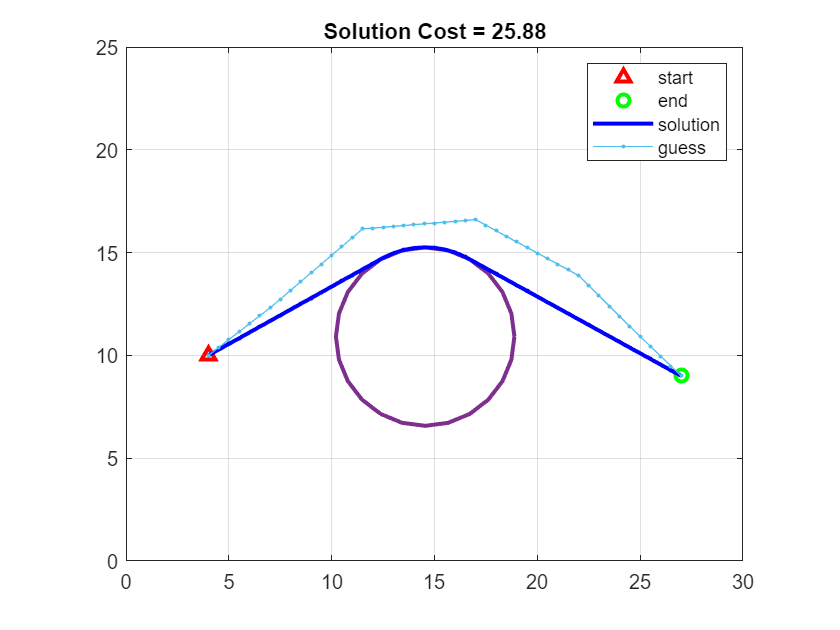

solution_cost = find_path_cost([x_out', y_out']);

% plot results
opt_results = outputFcn_global_data; % This data can be used with create_results_gif.m to create a gif of the minimization.
figure(3)
y_out = [y0 x yf];
x_out = x_span;
plot_env(x_start,x_end,obstacles)
plot_solution(x_out,y_out)
plot_guess(x_out,y_span_guess) 
title_name = sprintf('Solution Cost = %.2f',solution_cost);
title(title_name)
make_legend('start','end','','solution','guess')

### Minimization Visulization:

If "guess_below" is selected for our guess, the minimization solution iterations can be seen below.  This guess resulted in a solution cost of 23.81

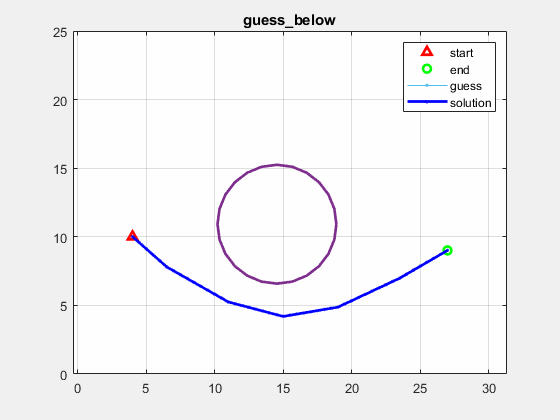

If "guess_above" is selected, the gif results are shown here.  Note that this guess resulted in a solution cost of 25.88

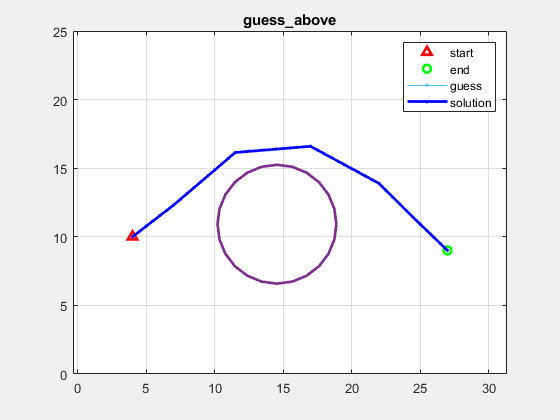

As you can see from these results, the quality of our solution is dependent on our initial guess.  This means our problem formulation will only result in a locally optimal solution.  For the one obstacle case, this is trivial for us to get around as we can just try solving the problem with a guess above and a guess below, using the smallest of the two costs.  However, as the number of obstacles grows, the number of potential inital guesses grows, resulting in poor scaling of this method with obstacle number.  The challenge of this can be seen by redoing this script with ginput enabled and selecting an obstacle course with a higher number of obstacles.

### Find Multi-Obstacle Optimal Solution:

Now that you have completed the document, I challenge you to try and find the optimal solution for obstacle courses with a higher numbers of obstacles.  You will need to create your own guesses for courses with higher numbers of obstacles.  To do this, enable ginput at the beginning of document and follow interface commands for creating an initial guess.  

For further investigation, you can also use the script short_dist_multi_obs.m, which this livescript is based on.  This script uses the ginput interface for easily making initial guesses for our optimizer.  The code used for this is available at [https://github.com/rpalfini/discrete_path_find.git](https://github.com/rpalfini/discrete_path_find.git)